led_center = zeros(1, 3000);
led_choice = zeros(1, 3000);

cue_tone = zeros(1, 3000);
uncue_tone = zeros(1, 3000);

poke_center = zeros(1, 3000);
poke_choice = zeros(1, 3000);


c_led = [240 160 40] / 255;
c_tone = [30 144 255] / 255;
c_poke = [0 0 0];

dur_fp = 1500;
dur_tone = 300;
dur_rt = 200;
dur_mt = 400;
dur_drink = 300;

t_cent_in = 500;
t_fp_end = t_cent_in + dur_fp;
t_cent_out = t_fp_end + dur_rt;

t_cue_off = t_fp_end + dur_tone;
t_uncue_off = t_cent_out + dur_tone;

t_choice_in = t_cent_out + dur_mt;
t_choice_out = t_choice_in + dur_drink;


led_center(1:t_cent_in) = 1;
led_choice(t_cent_in:t_choice_in) = 1;

cue_tone(t_fp_end:t_cue_off) = 1;
uncue_tone(t_cent_out:t_uncue_off) = 1;

poke_center(t_cent_in:t_cent_out) = 1;
poke_choice(t_choice_in:t_choice_out) = 1;


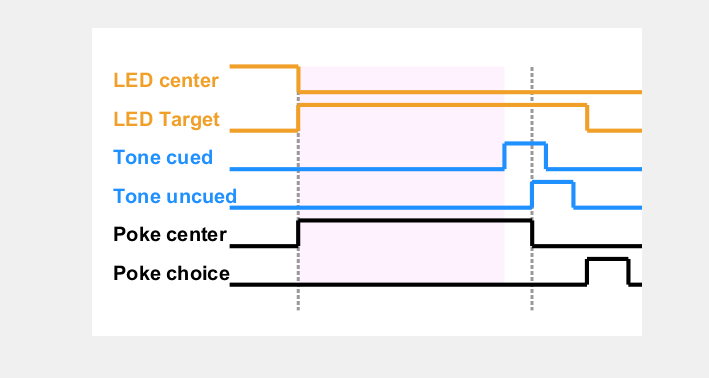

figure('Visible', 'on', 'Units', 'centimeters', 'Position', [2 2 15 8]);
ax = axes();
set(ax, 'Color', 'w', 'XColor', 'none', 'YColor', 'none', 'NextPlot', 'add');

fill([t_cent_in t_fp_end t_fp_end t_cent_in], [0 0 8.5 8.5], 'r', 'FaceColor', 'm', 'FaceAlpha', .05, 'EdgeColor', 'none');

plot([t_cent_in t_cent_in], [-1 8.5], ':', 'Color', [.6 .6 .6], 'LineWidth', 1.8);
plot([t_cent_out t_cent_out], [-1 8.5], ':', 'Color', [.6 .6 .6], 'LineWidth', 1.8);

stairs(led_center+7.5, 'LineWidth', 2.5, 'Color', c_led);
stairs(led_choice+6, 'LineWidth', 2.5, 'Color', c_led);

stairs(cue_tone+4.5, 'LineWidth', 2.5, 'Color', c_tone);
stairs(uncue_tone+3, 'LineWidth', 2.5, 'Color', c_tone);

stairs(poke_center+1.5, 'LineWidth', 2.5, 'Color', c_poke);
stairs(poke_choice, 'LineWidth', 2.5, 'Color', c_poke);

xlim([-1000 3000])

text(-850, 8, 'LED center', 'Color', c_led, 'FontSize', 12, 'FontWeight', 'bold');
text(-850, 6.5, 'LED Target', 'Color', c_led, 'FontSize', 12, 'FontWeight', 'bold');
text(-850, 5, 'Tone cued', 'Color', c_tone, 'FontSize', 12, 'FontWeight', 'bold');
text(-850, 3.5, 'Tone uncued', 'Color', c_tone, 'FontSize', 12, 'FontWeight', 'bold');
text(-850, 2, 'Poke center', 'Color', c_poke, 'FontSize', 12, 'FontWeight', 'bold');
text(-850, .5, 'Poke choice', 'Color', c_poke, 'FontSize', 12, 'FontWeight', 'bold');


exportgraphics(gcf, 'task_paradigm.jpg', 'Resolution', 600);